# 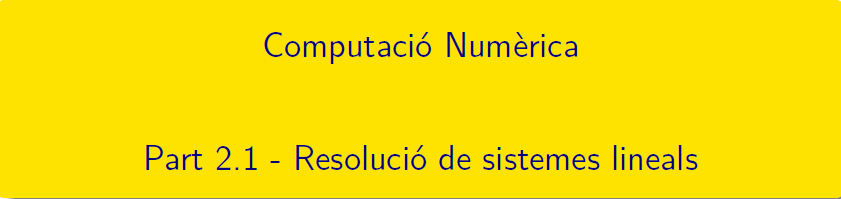

=====================================================================================

# TEMA 2 Àlgebra lineal numèrica (I)

## Part 2.0 - Vectors, Matrius i Normes

[Matrius de Matlab](https://es.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html) (resum de com treballar amb matrius)

Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

#### Radi espectral (pàg 16, bloc 0)

Càlcul de valors i vectors propis en Matlab®: consulteu [eigs ](https://www.mathworks.com/help/matlab/ref/eigs.html)i [eig](https://es.mathworks.com/help/matlab/ref/eig.html) 

H = hilb(4)
vaps = eig(H), rho = abs(eigs(H,1))

#### Nombre de condició d'una matriu (pàg 17, bloc 0)

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu 

[Condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html)

format longG
condN2 = cond(H), condN1 = cond(H,1), condNf = cond(H,'fro'), condNi = cond(H,inf)

## Part 2.1 - Resolució de sistemas d'equacions lineals

### Mètodes directes

El·liminació gaussiana, amb pivotament 


$$		\begin{array}{lcc}
		2x_1+4x_2+x_3 & = & 1\,,\\
		8x_1-x_2+3x_3 & = & 0\,,\\
		2x_1+5x_2 & = & 0\,.\\
		\end{array}$$


format shortG
A = [2 4 1; 8 -1 3; 2 5 0]; b = [1; 0; 0]; AM = [A,b];

Enllaç[ Numerical Computing with MATLAB®](https://es.mathworks.com/moler/chapters.html)

Cleve Moler (2021). Numerical Computing with MATLAB (https://www.mathworks.com/matlabcentral/fileexchange/37976-numerical-computing-with-matlab), MATLAB Central File Exchange. Retrieved February 25, 2021.

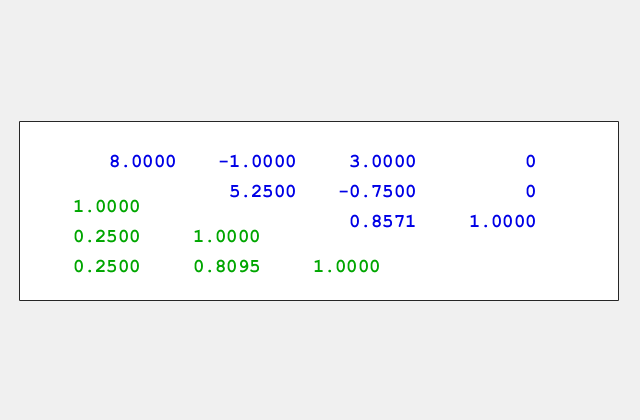

% Funció de Cleve Moler, llibre Numerical Computing with Matlab
[L,U,pv,qv] = lugui(AM);        

% Solució sistema
Pb = AM(pv,qv); Pb=Pb(:,end);
% 1) Ly=Pb
y = linsolve(L,Pb)

y =      0
     0
     1


% 2) Ux=y 
x = linsolve(U(:,1:end-1),y)

x =      -0.41667
      0.16667
       1.1667


Què passa si el pivot del pas k és zero?


$$\begin{array}{rrr}
	x_1+\,3x_2+\ x_3 & = & -3\,,\\
	3x_1+9x_2+4x_3 & = & -7\,,\\
	2x_1-\ x_2+\ x_3 & = & 6\,.\\
	\end{array}$$


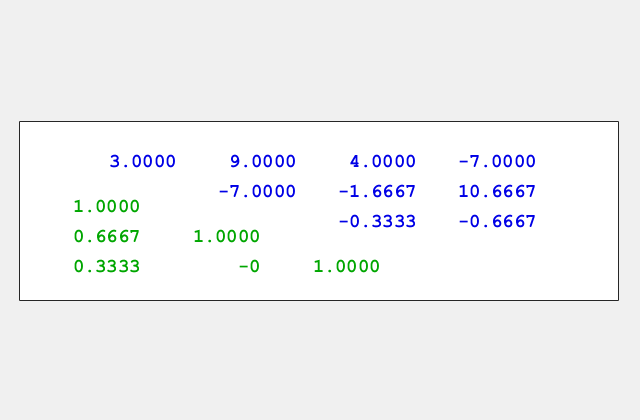

A =[ 1 3 1 -3; 3 9 4 -7; 2 -1 1 6];
[L,U,pv,qv] = lugui(A);        

% Solució sistema
Pb = AM(pv,qv); Pb=Pb(:,end);
% 1) Ly=Pb
y = linsolve(L,Pb)
% 2) Ux=y 
x = linsolve(U(:,1:end-1),y)

A = [6 2 1 -1; 2 4 1 0; 1 1 4 -1; -1 0 -1 3];
b = [1;2; 3;4];
[L,U,P] = lu(A);   %lugui(A)
% Primer pas, resoldre Ly=Pb
y = linsolve(L, P*b)      % y = L\P*b
% Segon pas, resoldre Ux=y
x = linsolve(U,y)
xn = A\b

#### Factoritzacions en Matlab®

Consulteu [LU, Txoleski i QR](https://es.mathworks.com/help/matlab/math/factorizations.html)

Obtindre les diferents factoritzacions de la matriu A


$$	$$ A=\left ( \begin{array}{rrrr}
	6 & 2 & 1 & -1 \\
	2 & 4 & 1 & 0 \\
	1 & 1 & 4 & -1 \\
	-1 & 0 & -1 & 3
	\end{array}\right )$$$$


format shortG
A=[6 2 1 -1;-2 4 1 0; 1 1 4 -1; -1 0 -1 3]; b=[0;7;-1; 2];
[L,U] = lu(A)                         % x = U\(L\b)
y = linsolve(L,b); x = linsolve(U,y)
X = U\(L\b)

[R, iflag] = chol(A)                  % iflag = 0, indica simètrica definida positiva
y = linsolve(R',b); x = linsolve(R,y)  % x = R\(R'\b)

[Q,R] =qr(A)
format shortG, Q'*Q
norm(A-Q*R)                           % verifiquem que A=QR, dins de la precisió de la màquina
y = Q'*b; x = linsolve(R,y)

Trobeu la factorització A = R'R i resoleu després el sistema lineal Ax=b


$$A=\left( \begin{array}{rrrr}
16 & 4 & 0 & -4 \\
 4 & 5 & 2 & -1 \\
 0 & 2 & 2 & -2\\
-4 & -1 & -2 & 6
\end{array} \right)$$
    
$$b=\left(\begin{array}{r}   8\\ -2\\-4\\ 3\end{array} \right) 
\quad \Longrightarrow \quad R=\left( \begin{array}{rrrr}
4 & 1 & 0 & -1 \\
0 & 2 & 1 & 0 \\
0 & 0 & 1 & -2\\
0 & 0 & 0 & 1
\end{array} \right)$$


A = [16 4 0 -4; 4 5 2 -1; 0 2 2 -2; -4 -1 -2 6]; b = [8; -2; -4;3];
R = chol(A)
y = linsolve(R',b); x = linsolve(R,y)

#### Vector residu i nombre de condició


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8 & 7 & 32.1\\
7 & 5 & 6 & 5 & 22.9\\
8 & 6 & 10 & 9 & 33.1\\
7 & 5 & 9 & 10 & 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]
% Sistema lineal 
b1 = [32; 23; 33; 31];
b2 = [32.1; 22.9; 33.1; 30.9];
B = [b1,b2], x = A\B
fprintf('paràmetres de condicionament\n'),K = cond(A,1), RK = rcond(A)
fprintf('vector residu\n'),rx = A*x-B

### Mètodes iteratius

Determineu  les matrius d'iteració del mètode de Jacobi i del mètode de Gauss-Seidel del sistema Ax=b donat per 


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$
 

A = [1 0 1; -1 1 0; 1 2 3]; b=[4;1;-4];

D = diag(diag(A));
d = diag(1 ./diag(A));
L = tril(A,-1);
U = triu(A,1);

Matrius de Jacoi

DI = inv(D);
BJ =-DI*(L+U);
cJ = DI*b;

Matrius de Gauss-seidel

DI = inv(D+L);
Bgs =-DI*U;
cgs = DI*b;


Convergència???

rhoJ = abs(eigs(BJ,1))          % radi = vap de mòdul màxim

rhoJ =      1


rhogs = abs(eigs(Bgs,1))        % radi = vap de mòdul màxim

rhogs =      1


% if (rhoJ >= 1) 
%     fprintf('mètode de JACOBI divergent');
% end
% if (rhogs >= 1) 
%     fprintf('mètode de Gauss-Seidel divergent');
% end

Determineu les 10 primeres iteracions dels mètodes presentats a classe: Jacobi, Gauss-Seidel, SOR prenent $x^{(0)}=(0\,,0\,,0\,,0)^{t}$ del sistema Ax = b donat per


$$A=\left( \begin{array}{rrrr}
10 & -1 & 2 & 0 \\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)$$
 

A=[10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b=[6;25;-11;15];
[rhoJ, rhoGS, rhoJWO, rhoGWO]=radis(A,20)
% exemple_jacobi
% exemple_gseidel
% exemple_SORgseidel

### Mètode dels mínims quadrats

**Sistemes lineals sobredeterminats**


$$\begin{array}{rrr}
	x_1+x_2 & = &1\,,\\
	x_1+2x_2 & = & 2\,,\\
	x_1+3x_2 & = & 5\,.\\
	\end{array}$$


% A1 = [1 1; 1 2], b1 = [1;2]
% A3 = [1 1; 1 3], b2 = [1;5]
% A2 = [1 2; 1 3], b3 = [2;5]
% A = [1 1; 1 2; 1 3], b = [1;2;5]

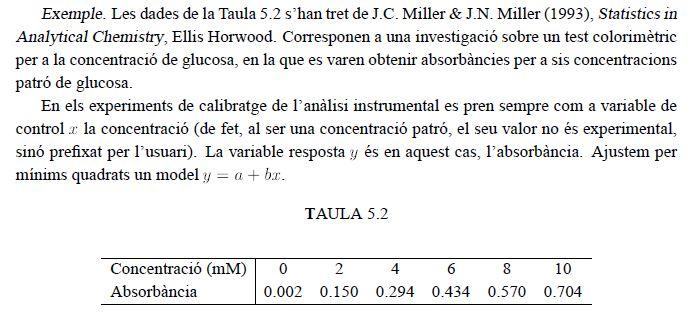

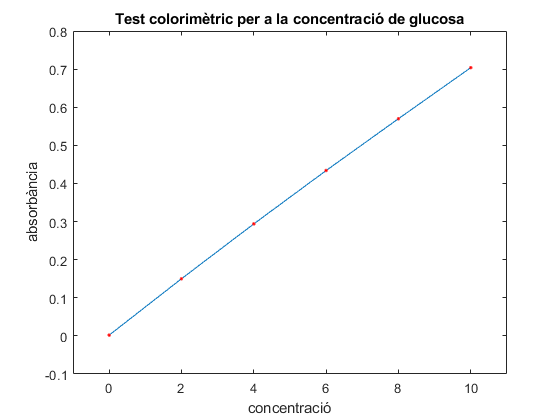

x = [0:2:10]';    % Concentració(mM)
y = [0.002; 0.150; 0.294; 0.434; 0.570; 0.704]; % Absorbència
plot(x,y,x,y,'r.')
axis([-1,11,-0.1,0.8])
xlabel('concentració')
ylabel('absorbància')
title('Test colorimètric per a la concentració de glucosa')

A = [ones(size(x)),x]

A =      1     0
     1     2
     1     4
     1     6
     1     8
     1    10


% A'Ax=A'b
B = A'*A, c = A'*y      % Equacions normals

B =      6    30
    30   220


c =         2.154
        15.68


coeff_recta = linsolve(B,c)

coeff_recta =     0.0082857
     0.070143


r = y-A*coeff_recta, norm(r)

r =    -0.0062857
    0.0014286
    0.0051429
    0.0048571
   0.00057143
   -0.0057143


ans =      0.011161


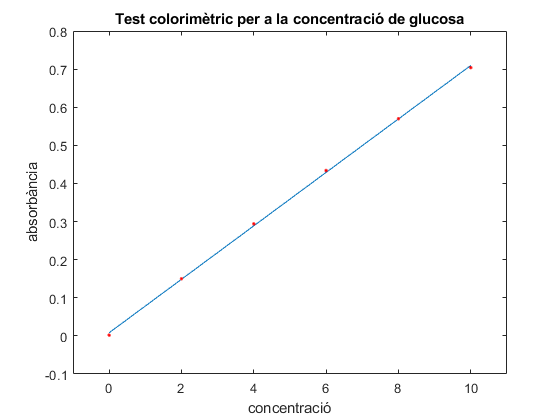

t = linspace(0,10);
a = coeff_recta(1); b = coeff_recta(2);
recta = a+b*t;
plot(t,recta,x,y,'r.')
axis([-1,11,-0.1,0.8])
xlabel('concentració')
ylabel('absorbància')
title('Test colorimètric per a la concentració de glucosa')

%%% Però matlab ja ho fa
A, y, z = linsolve(A,y)

A =      1     0
     1     2
     1     4
     1     6
     1     8
     1    10


y =         0.002
         0.15
        0.294
        0.434
         0.57
        0.704


z =     0.0082857
     0.070143
